# Tarea 1

Raúl Correa Ocañas

A01722401

18 de mayo de 2023

clc
dpdt = @(t,phi) -2.2067 * 10^-12*(phi^4-81*10^8);
phi(1) = 1200; % Kelvin
h = 240; % Paso de 240s
t_1 = 0; % tiempo inicial
t_f = 480; % tiempo final = 480s

[t, phi_heun] = Heun(dpdt,t_1,t_f,phi,h);
[t, phi_mid] = PuntoMedio(dpdt,t_1,t_f,phi,h);
[t, phi_ralston] = Ralston(dpdt,t_1,t_f,phi,h);

phi_heun

phi_heun = 1.0e+03 *

    1.2000    0.6552    0.5843


phi_mid

phi_mid = 1.0e+03 *

    1.2000    1.1080    0.9769


phi_ralston

phi_ralston = 1.0e+03 *

    1.2000    0.8309    0.6900


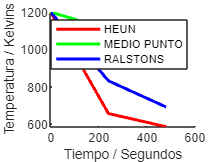

figure(1)
hold on
a1 = plot(t, phi_heun, 'r', 'LineWidth', 2);    % Heun - rojo
a2 = plot(t, phi_mid, 'g', 'LineWidth', 2);     % Medio Punto - verde
a3 = plot(t, phi_ralston, 'b', 'LineWidth', 2); % Ralston's - azul
hold off

xlabel('Tiempo / Segundos')
ylabel('Temperatura / Kelvins')
legend([a1,a2,a3], 'HEUN', 'MEDIO PUNTO', 'RALSTONS')

## Método de Heun

function [t,phi] = Heun(f,t_1,t_f,phi,h)
    t = t_1:h:t_f;
    for i = 1:length(t)-1
        k1 = f(t(i), phi(i));
        k2 = f(t(i) + h, phi(i) + k1*h);
        phi(i+1) = phi(i) + h*(k1 + k2)/2;
    end
end

## Método de Punto Medio

function [t,phi] = PuntoMedio(f,t_1,t_f,phi,h)
    t = t_1:h:t_f;
    for i = 1:length(t)-1
        k1 = f(t(i), phi(i));
        k2 = h*f(t(i) + h/2, phi(i) + k1*h/2);
        phi(i+1) = phi(i) + k2;
    end
end

## Método de Ralston

function [t,phi] = Ralston(f,t_1,t_f,phi,h)
    t = t_1:h:t_f;
    for i = 1:length(t)-1
        k1 = h*f(t(i), phi(i));
        k2 = h*f(t(i) + 3*h/4, phi(i) + 3*k1/4);
        phi(i+1) = phi(i) + k1/3 + 2*k2/3;
    end
end